# Modeling and Autotuning of the iCub 2 head

## Run the simplified project

We first load the project dedicated to modelling and autotuning.

if(currentProject().Name == "neck-study-full")
    close(currentProject());
end

if isempty(matlab.project.rootProject)
    open('model-simplified/neck-study-simplified.prj')
end

### Create uncertain transfer functions

Our objective is to control roll and pitch of the head through discrete PID controllers.

 To do so, we use a Simscape Multibody model made by lumped up components. This model is used to create two decoupled systems, linearized at different operating points.

create_uncertain_models

ans = 'Finding operating point for pitch=-40.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(7.10543e-15) lumped_neck_with_motor_pitch/yp
(7.10543e-15) lumped_neck_with_motor_pitch/yp

Operating point specifications were successfully met.



ans = 'Finding operating point for pitch=0.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(0.00000e+00) There are no errors in the operating point search constraints.
(0.00000e+00) There are no errors in the operating point search constraints.

Operating point specifications were successfully met.



ans = 'Finding operating point for pitch=22.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(3.55271e-15) lumped_neck_with_motor_pitch/yp
(3.55271e-15) lumped_neck_with_motor_pitch/yp

Operating point specifications were successfully met.



ans = 'Finding operating point for roll=-20.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(3.55271e-15) lumped_neck_with_motor_roll/yr
(3.55271e-15) lumped_neck_with_motor_roll/yr

Operating point specifications were successfully met.



ans = 'Finding operating point for roll=0.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(0.00000e+00) There are no errors in the operating point search constraints.
(0.00000e+00) There are no errors in the operating point search constraints.

Operating point specifications were successfully met.



ans = 'Finding operating point for roll=20.0'

Optimizing to solve for all desired dx/dt=0, x(k+1)-x(k)=0, and y=ydes.
 
(Maximum Error)  Block
 ---------------------------------------------------------
(3.55271e-15) lumped_neck_with_motor_roll/yr
(3.55271e-15) lumped_neck_with_motor_roll/yr

Operating point specifications were successfully met.



Here is the nominal transfer function between  the pitch PID controller and the pitch angle:

zpk(tfu_pitch.NominalValue)

ans =
 
               3.0588e06 (s+10)
  -------------------------------------------
  (s+1.587e04) (s+60.44) (s+10.08) (s-0.8391)
 
Continuous-time zero/pole/gain model.



And here is the nominal transfer function between the roll PID controller and the roll angle:

zpk(tfu_roll.NominalValue)

ans =
 
              3.6843e06 (s+10)
  ----------------------------------------
  (s+1.597e04) (s+72.3) (s+10.06) (s-0.73)
 
Continuous-time zero/pole/gain model.



Since the head is an inverted pendulum with two degrees of freedom, we find unstable poles that constitute the dominant modes of the two systems. The unstable poles are modelled with uncertainties depending on the chosen operating points.

### Launch autotuning algorithm

After computing the models, we can launch the automated robust tuning algorithm. The method works by creating two feedback systems made by the models and two decoupled continuous PID controllers. 

The controllers are then tuned iteratively with built-in robust algorithms. Finally, the controllers are discretized, for implementation on uC.

Nominal tuning:
Design 1: Soft = 1.44, Hard = 1.0275
Design 2: Soft = 1.44, Hard = 1.0275
Design 3: Soft = 1.44, Hard = 1.0275
Design 4: Soft = 1.44, Hard = 1.0275
Design 5: Soft = 1.44, Hard = 1.0275
Design 6: Soft = 1.44, Hard = 1.0275

Robust tuning of Design 2:
Soft: [1.44,Inf], Hard: [1.03,2.52], Iterations = 54
Soft: [1.46,Inf], Hard: [1.34,1.65], Iterations = 34
Soft: [1.48,Inf], Hard: [1.5,1.5], Iterations = 27
Final: Soft = 1.48, Hard = 1.5006, Iterations = 115

Robust tuning of Design 5:
Soft: [1.44,Inf], Hard: [1.03,2.52], Iterations = 59
Soft: [1.46,Inf], Hard: [1.34,1.65], Iterations = 29
Soft: [1.48,Inf], Hard: [1.5,1.5], Iterations = 27
Final: Soft = 1.48, Hard = 1.5006, Iterations = 115

Robust tuning of Design 6:
Soft: [1.44,Inf], Hard: [1.03,2.52], Iterations = 55
Soft: [1.46,Inf], Hard: [1.34,1.65], Iterations = 29
Soft: [1.48,Inf], Hard: [1.5,1.5], Iterations = 27
Final: Soft = 1.48, Hard = 1.5006, Iterations = 111

Robust tuning of Design 1:
Soft: [1.44,Inf], Hard:

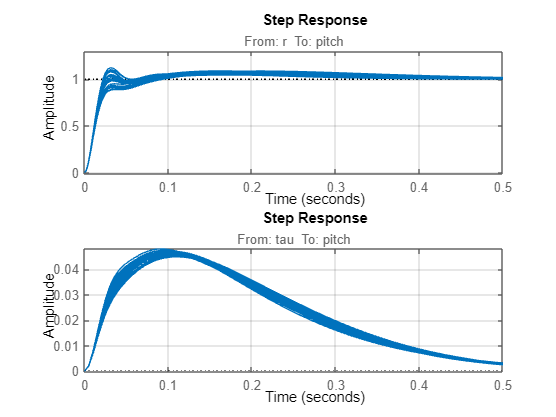

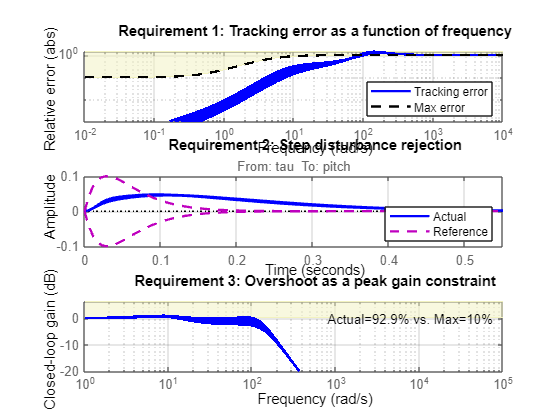

Nominal tuning:
Design 1: Soft = 1.43, Hard = 0.99957
Design 2: Soft = 1.43, Hard = 0.99852
Design 3: Soft = 1.43, Hard = 0.99992
Design 4: Soft = 1.43, Hard = 0.99978
Design 5: Soft = 1.43, Hard = 0.99919
Design 6: Soft = 1.43, Hard = 0.99963

Robust tuning of Design 3:
Soft: [1.43,Inf], Hard: [1,2.62], Iterations = 194
Soft: [1.46,Inf], Hard: [1.3,1.61], Iterations = 33
Soft: [1.48,Inf], Hard: [1.46,1.46], Iterations = 32
Final: Soft = 1.48, Hard = 1.4638, Iterations = 259

Robust tuning of Design 4:
Soft: [1.43,Inf], Hard: [1,2.62], Iterations = 173
Soft: [1.46,Inf], Hard: [1.3,1.61], Iterations = 33
Soft: [1.48,Inf], Hard: [1.46,1.46], Iterations = 32
Final: Soft = 1.48, Hard = 1.4638, Iterations = 238

Robust tuning of Design 6:
Soft: [1.43,Inf], Hard: [1,2.62], Iterations = 168
Soft: [1.46,Inf], Hard: [1.3,1.61], Iterations = 33
Soft: [1.48,Inf], Hard: [1.46,1.46], Iterations = 32
Final: Soft = 1.48, Hard = 1.4638, Iterations = 233

Robust tuning of Design 1:
Soft: [1.43,Inf], Ha

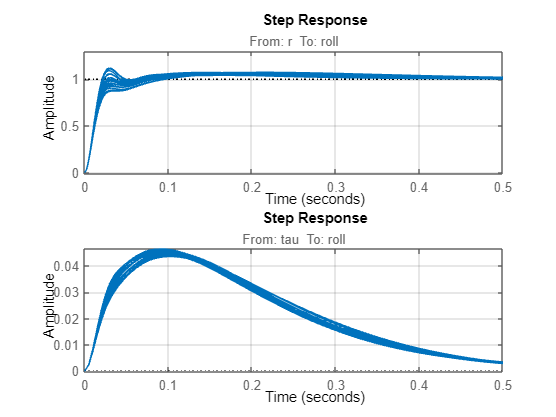

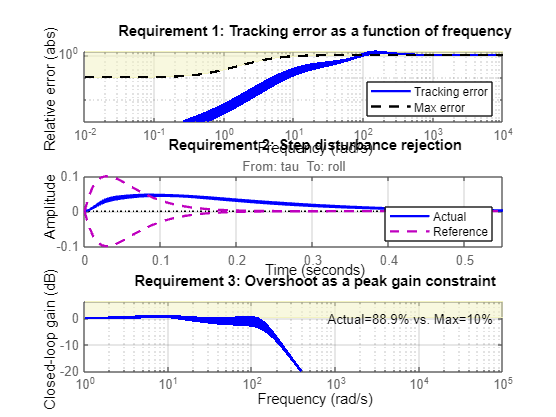

launch_autotune

## Run the full project

We load the project containing the full fledged model of the head, to validate the controller.

if(currentProject().Name == "neck-study-simplified")
    close(currentProject());
end

if isempty(matlab.project.rootProject)
    open('model-full/neck-study-full.prj')
end

#### Check if controllers exist

We load the .mat file containing the pitch and roll controllers if they are not instantiated.

if(isempty('Cz_pitch') || isempty('Cz_roll'))
    if(~exist('data/pitch_roll_controllers.mat','file'))
        error('Pitch and roll controllers not found.')
    else
        load('data/pitch_roll_controllers.mat');
    end
end

### Run the simulation

To validate the autotuned PID controllers we run a simulation containing the full-fledged Simscape Multibody model. The model is the result of the 

out = sim('models/neck_head_control.slx');